# Process Quantitative EPMA Maps

## Import Data

 

clear all; close all; 

load batlowK.mat
FL     = {'FontSize',16};
FS     = {'FontSize',12};
Fs     = {'FontSize',10};
TX     = {'Interpreter','Latex'};
TL     = {'TicklabelInterpreter','Latex'};
LW     = {'LineWidth',2};
MS     = {'MarkerSize',10};
UN     = {'Units','inches'};

addpath ./data
filename = "VIC09A_B2-2_Oxide_Image_Classify.DAT";

opts = delimitedTextImportOptions("NumVariables", 18);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "X", "Y", "NX", "NY", "NXY", "SiWT", "AlWT", "CaWT", "TiWT", "KWT", "PWT", "FeWT", "MnWT", "NaWT", "MgWT","OWT", "Total", "VarName18"];
opts.SelectedVariableNames = ["X", "Y", "NX", "NY", "NXY", "SiWT", "AlWT", "CaWT", "TiWT", "KWT", "PWT", "FeWT", "MnWT", "NaWT", "MgWT","OWT", "Total"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "VarName18", "TrimNonNumeric", true);
opts = setvaropts(opts, "VarName18", "ThousandsSeparator", ",");

% Import the data
DATtab = readtable(filename, opts);

disp('Data loaded successfully')

Data loaded successfully


## Convert data

 

% convert table to array
DATvec = table2array(DATtab);

% extract map dimensions
nx = max(DATvec(:,3));
nz = max(DATvec(:,4));
DATmap = reshape(DATvec,nx,nz,[]);
DATmap = permute(DATmap,[2,1,3]);

X  = DATmap(1,:,1).';
Z  = DATmap(:,1,2);

% sort oxides into standard sequence
%           Si Ti Al Fe Mg Ca  Na K  P  Mn O  Total
OxdInd   = [1, 4, 2, 7, 10, 3, 9, 5, 6, 8, 11, 12];
OxdNames = {'SiO2';'TiO2';'Al2O3';'FeO';'MgO';'CaO';'Na2O';'K2O'; 'P2O5'; 'MnO';'O';'Total'};
nc       = length(OxdInd);
Si = 1; Ti = 2; Al = 3; Fe = 4; Mg = 5; Ca = 6; Na = 7; K = 8; P = 9; Mn = 10; O = 11; Total = 12;
OxdVec = DATvec(:,5+OxdInd); OxdVec0 = OxdVec;
OxdMap = fliplr(DATmap(:,:,5+OxdInd));
OxdLim = {[0 90];[0 5];[0 30];[0 30];[0 30];[0 20];[0 10];[0 5];[0 5];[0 5]}; 

disp('Data converted successfully')

Data converted successfully


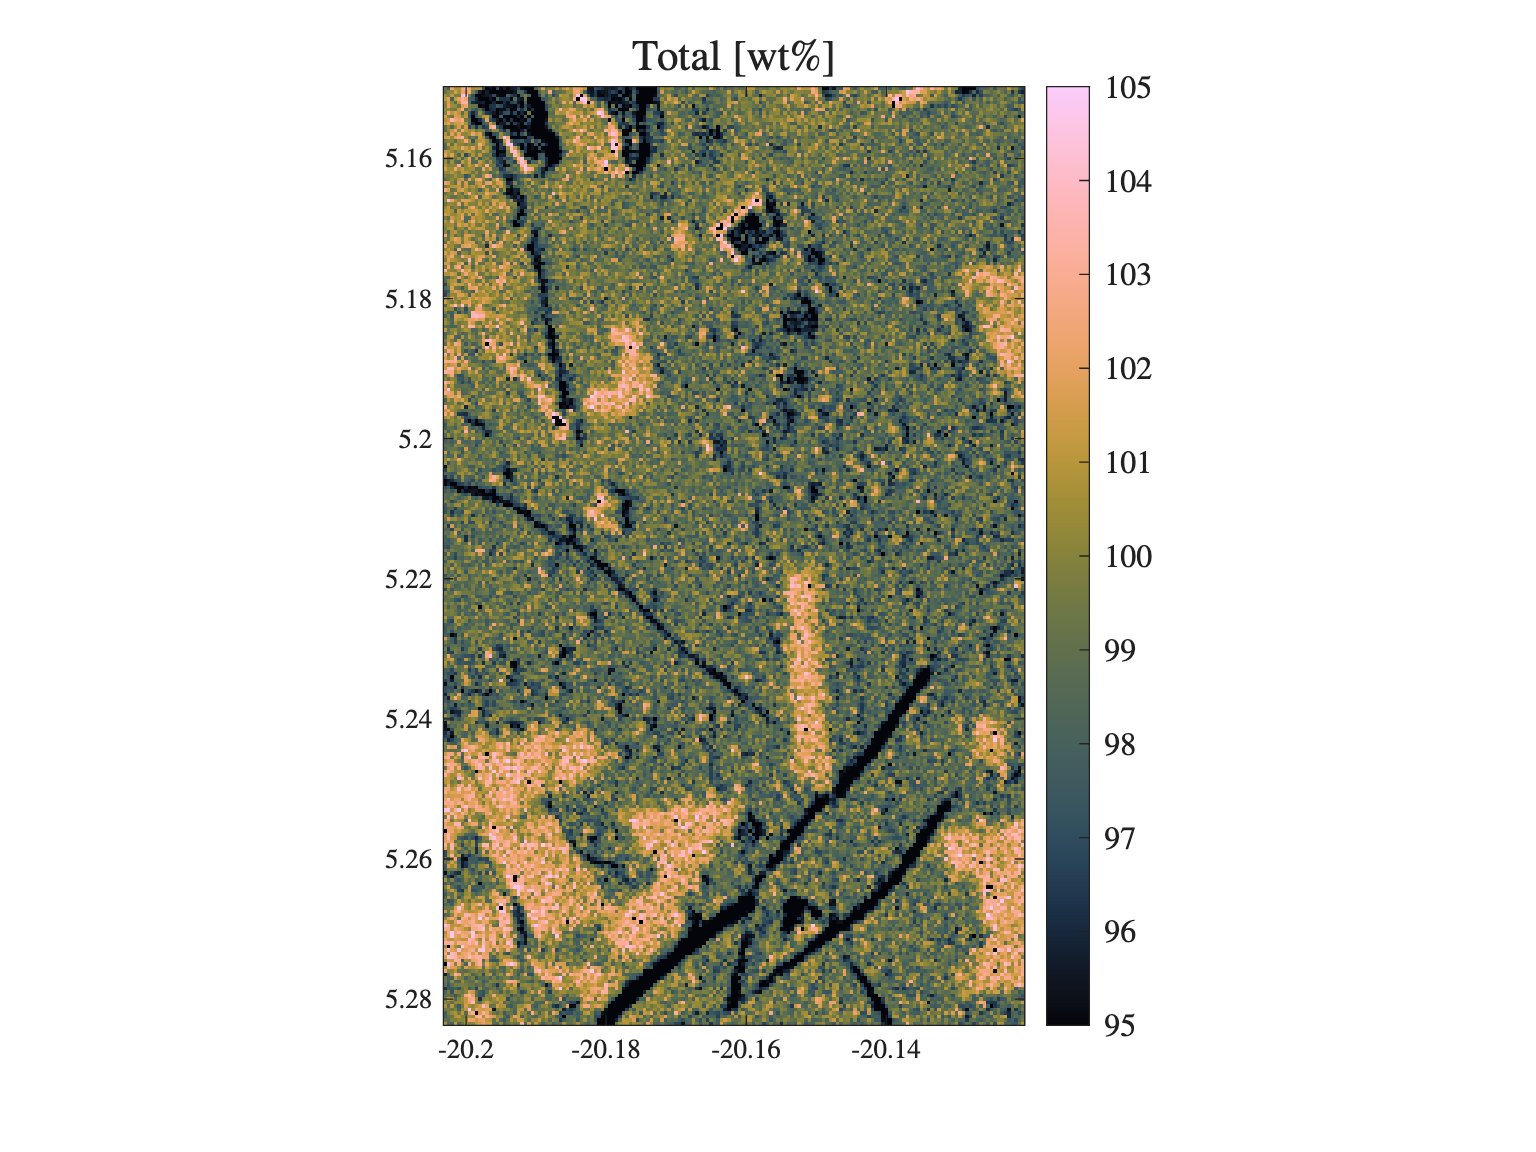

 

% extract valid totals
mintot =95;
maxtot =105;

valmap = OxdMap(:,:,Total)>mintot & OxdMap(:,:,Total)<maxtot;
valvec = OxdVec(:,Total)>mintot & OxdVec(:,Total)<maxtot;

fh1 = figure(1); clf;
set(fh1,UN{:},'Position',[1 1 8 6]);
imagesc(X,Z,OxdMap(:,:,Total).*valmap); axis equal tight; colormap(batlowK); colorbar(TL{:},FS{:}); 
clim([mintot,maxtot]);
set(gca,TL{:},Fs{:})
title('Total [wt\%]',TX{:},FL{:})

**Fig. 1:** Analytical totals of major oxide measurments of valid points between set min/max tolerance levels.

## Plot major element oxide maps

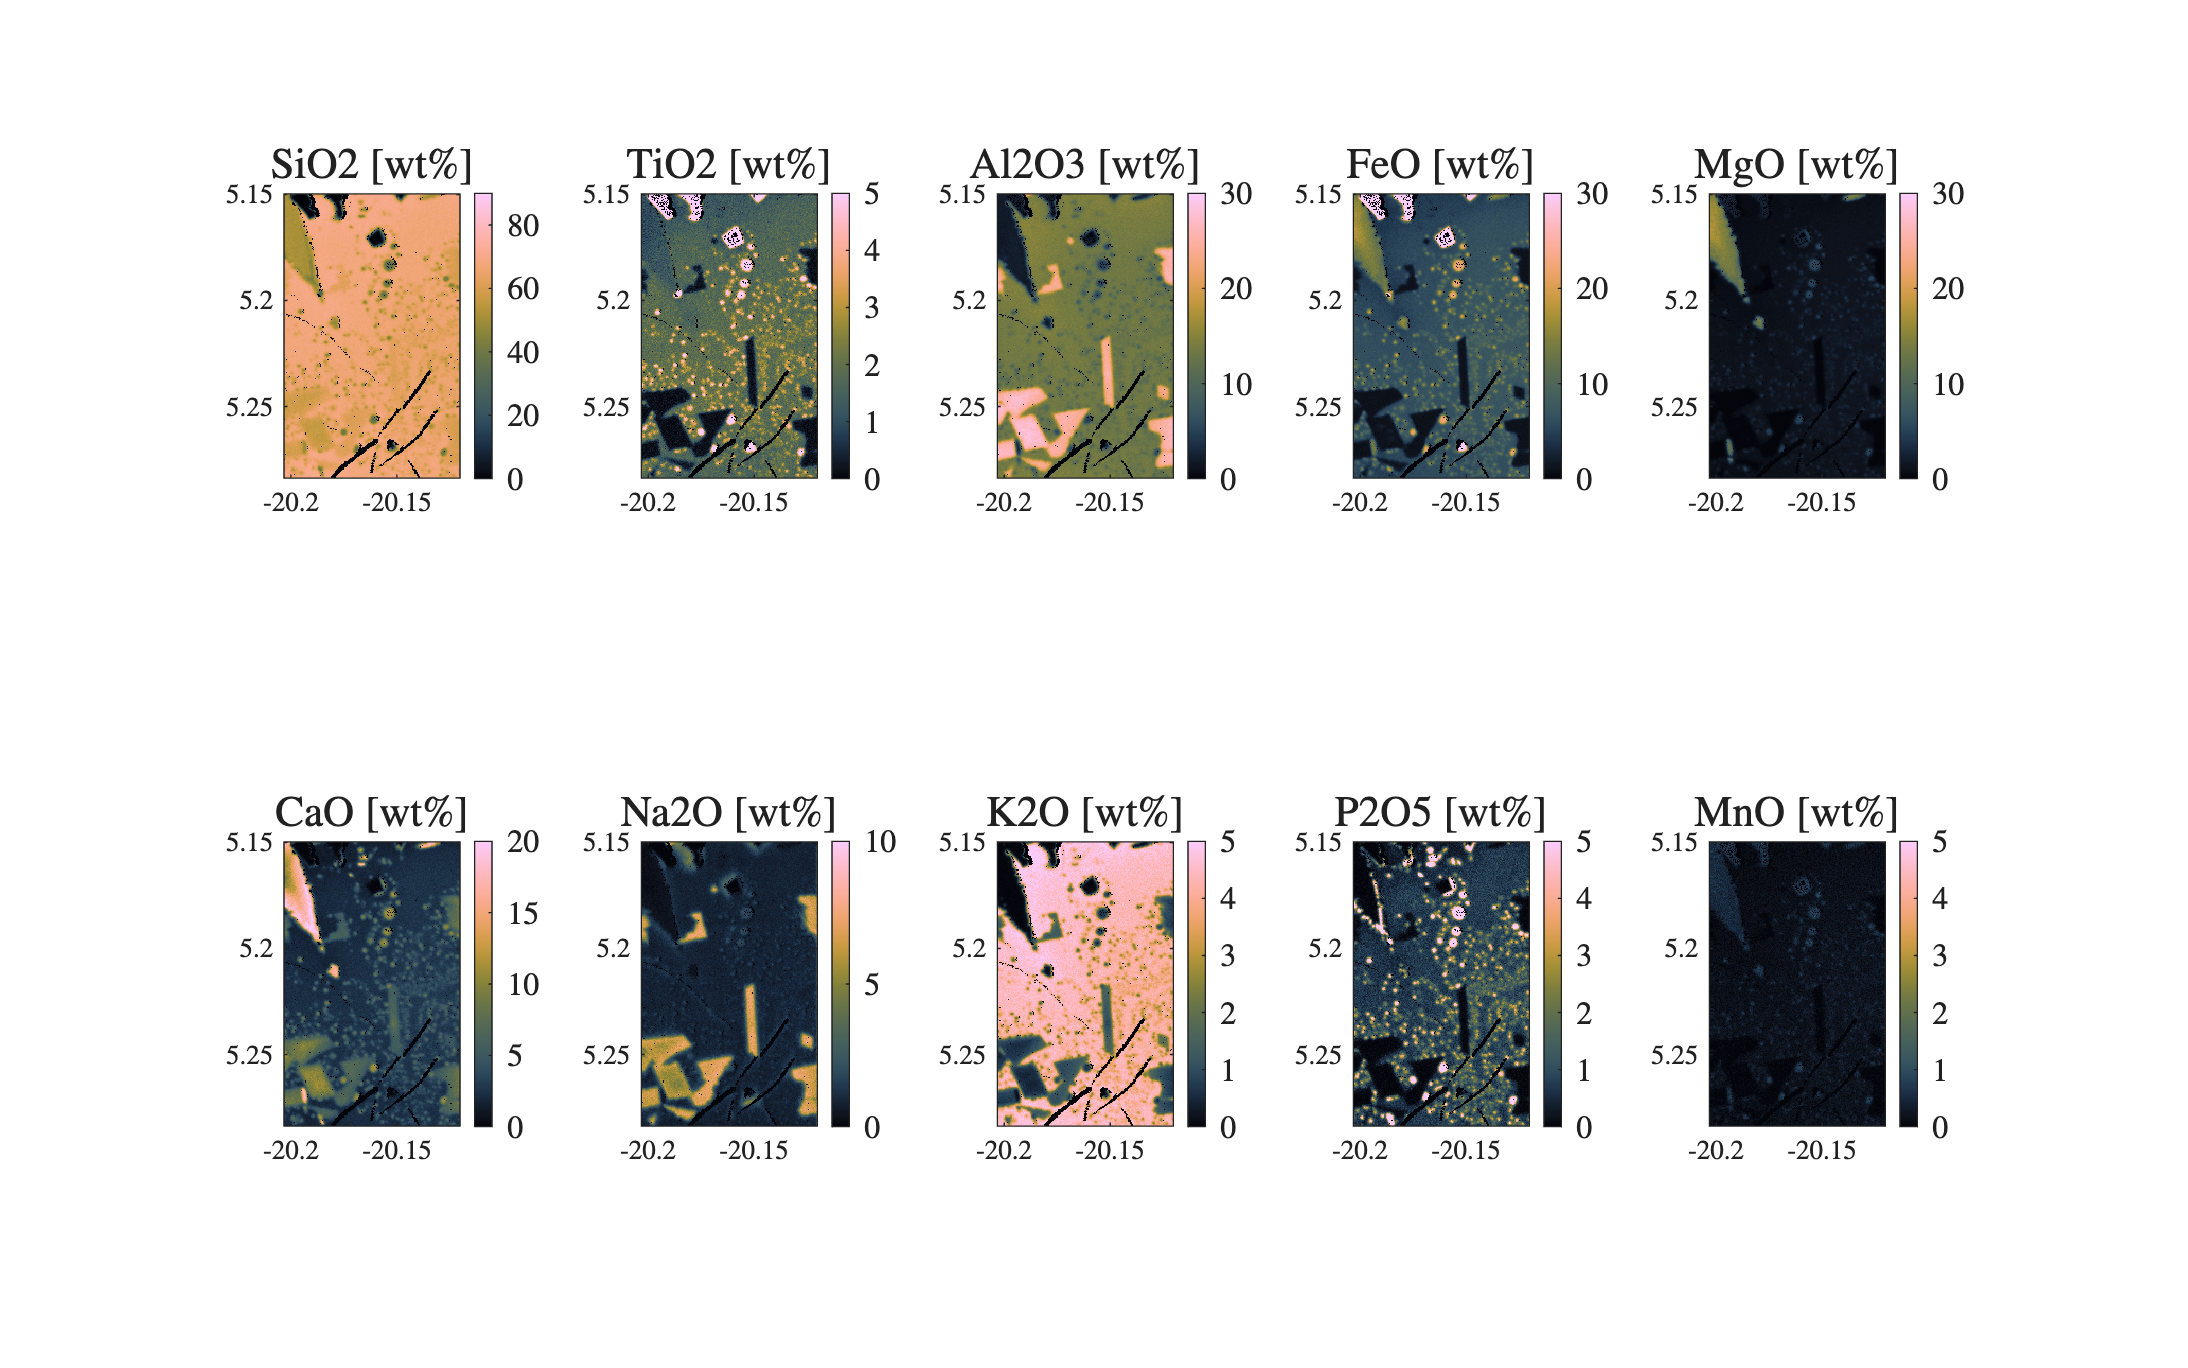

% plot oxide compositions

 

fh2 = figure(2); clf;
set(fh2,UN{:},'Position',[1 1 24 15]);
k  = nc-2;
if     k<=4;  kk = 2; kkk = 2; 
elseif k<=6;  kk = 2; kkk = 3;
elseif k<=8;  kk = 2; kkk = 4;
elseif k<=9;  kk = 3; kkk = 3;
elseif k<=10; kk = 2; kkk = 5;
end

ik = 1;
for ikk=1:kk
    for ikkk = 1:kkk
        subplot(kk,kkk,ik);
        imagesc(X,Z,OxdMap(:,:,ik).*valmap); axis equal tight; 
        colormap(batlowK); colorbar(TL{:},FS{:});
        clim(OxdLim{ik});
        set(gca,TL{:},Fs{:})
        title([OxdNames{ik},' [wt\%]'],TX{:},FL{:})
        ik = ik+1;
    end
end

**Fig. 2:** Major oxide concentrations; colorbar range cropped to improve readability.

## Plot Correlation Matrix

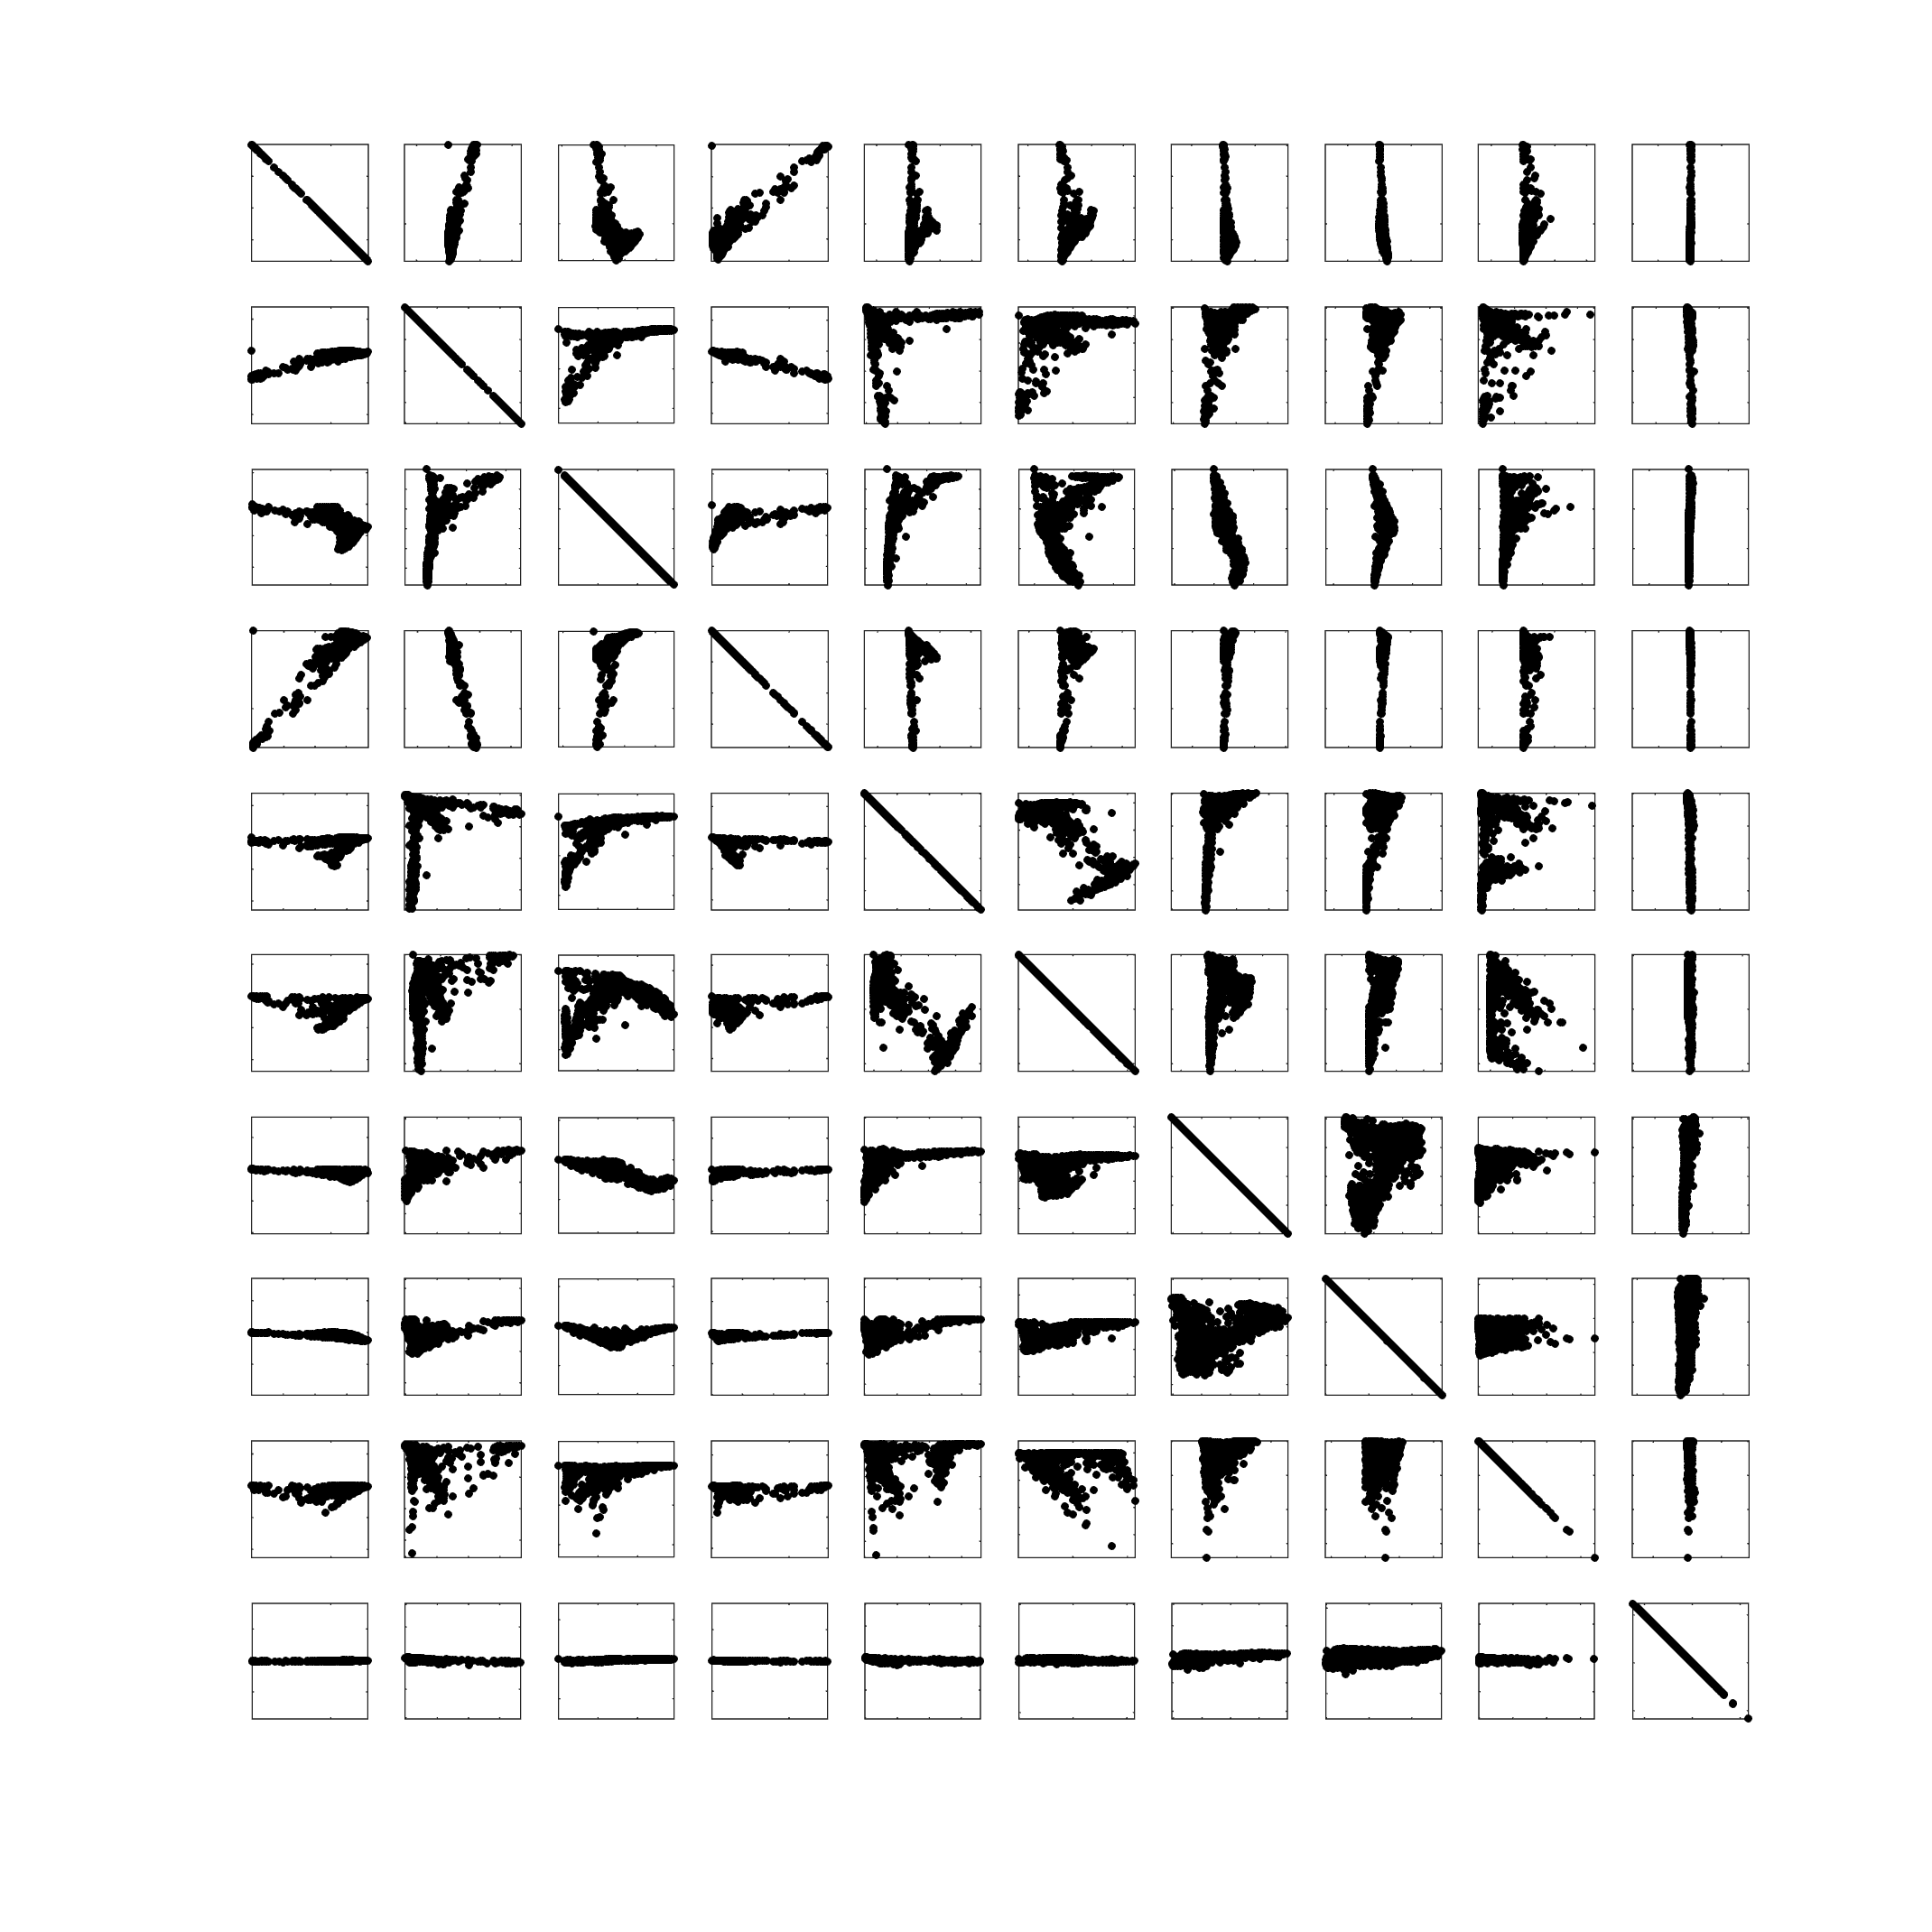

 

fh3 = figure(3); clf;
set(fh3,UN{:},'Position',[1 1 20 20]);
k  = nc-2;
ik = 1;
for kk=1:k
    for kkk = 1:k
        subplot(k,k,ik);
        plot(OxdVec(1:10:end,kkk).*valvec(1:10:end),OxdVec(1:10:end,kk).*valvec(1:10:end),'k.',MS{:}); axis ij equal;
        set(gca,'XTickLabels',[],'YTickLabels',[]);
        ik = ik+1;
    end
end

**Fig. 3:** Correlation between major oxide concentrations.

## Plot False Colour Images

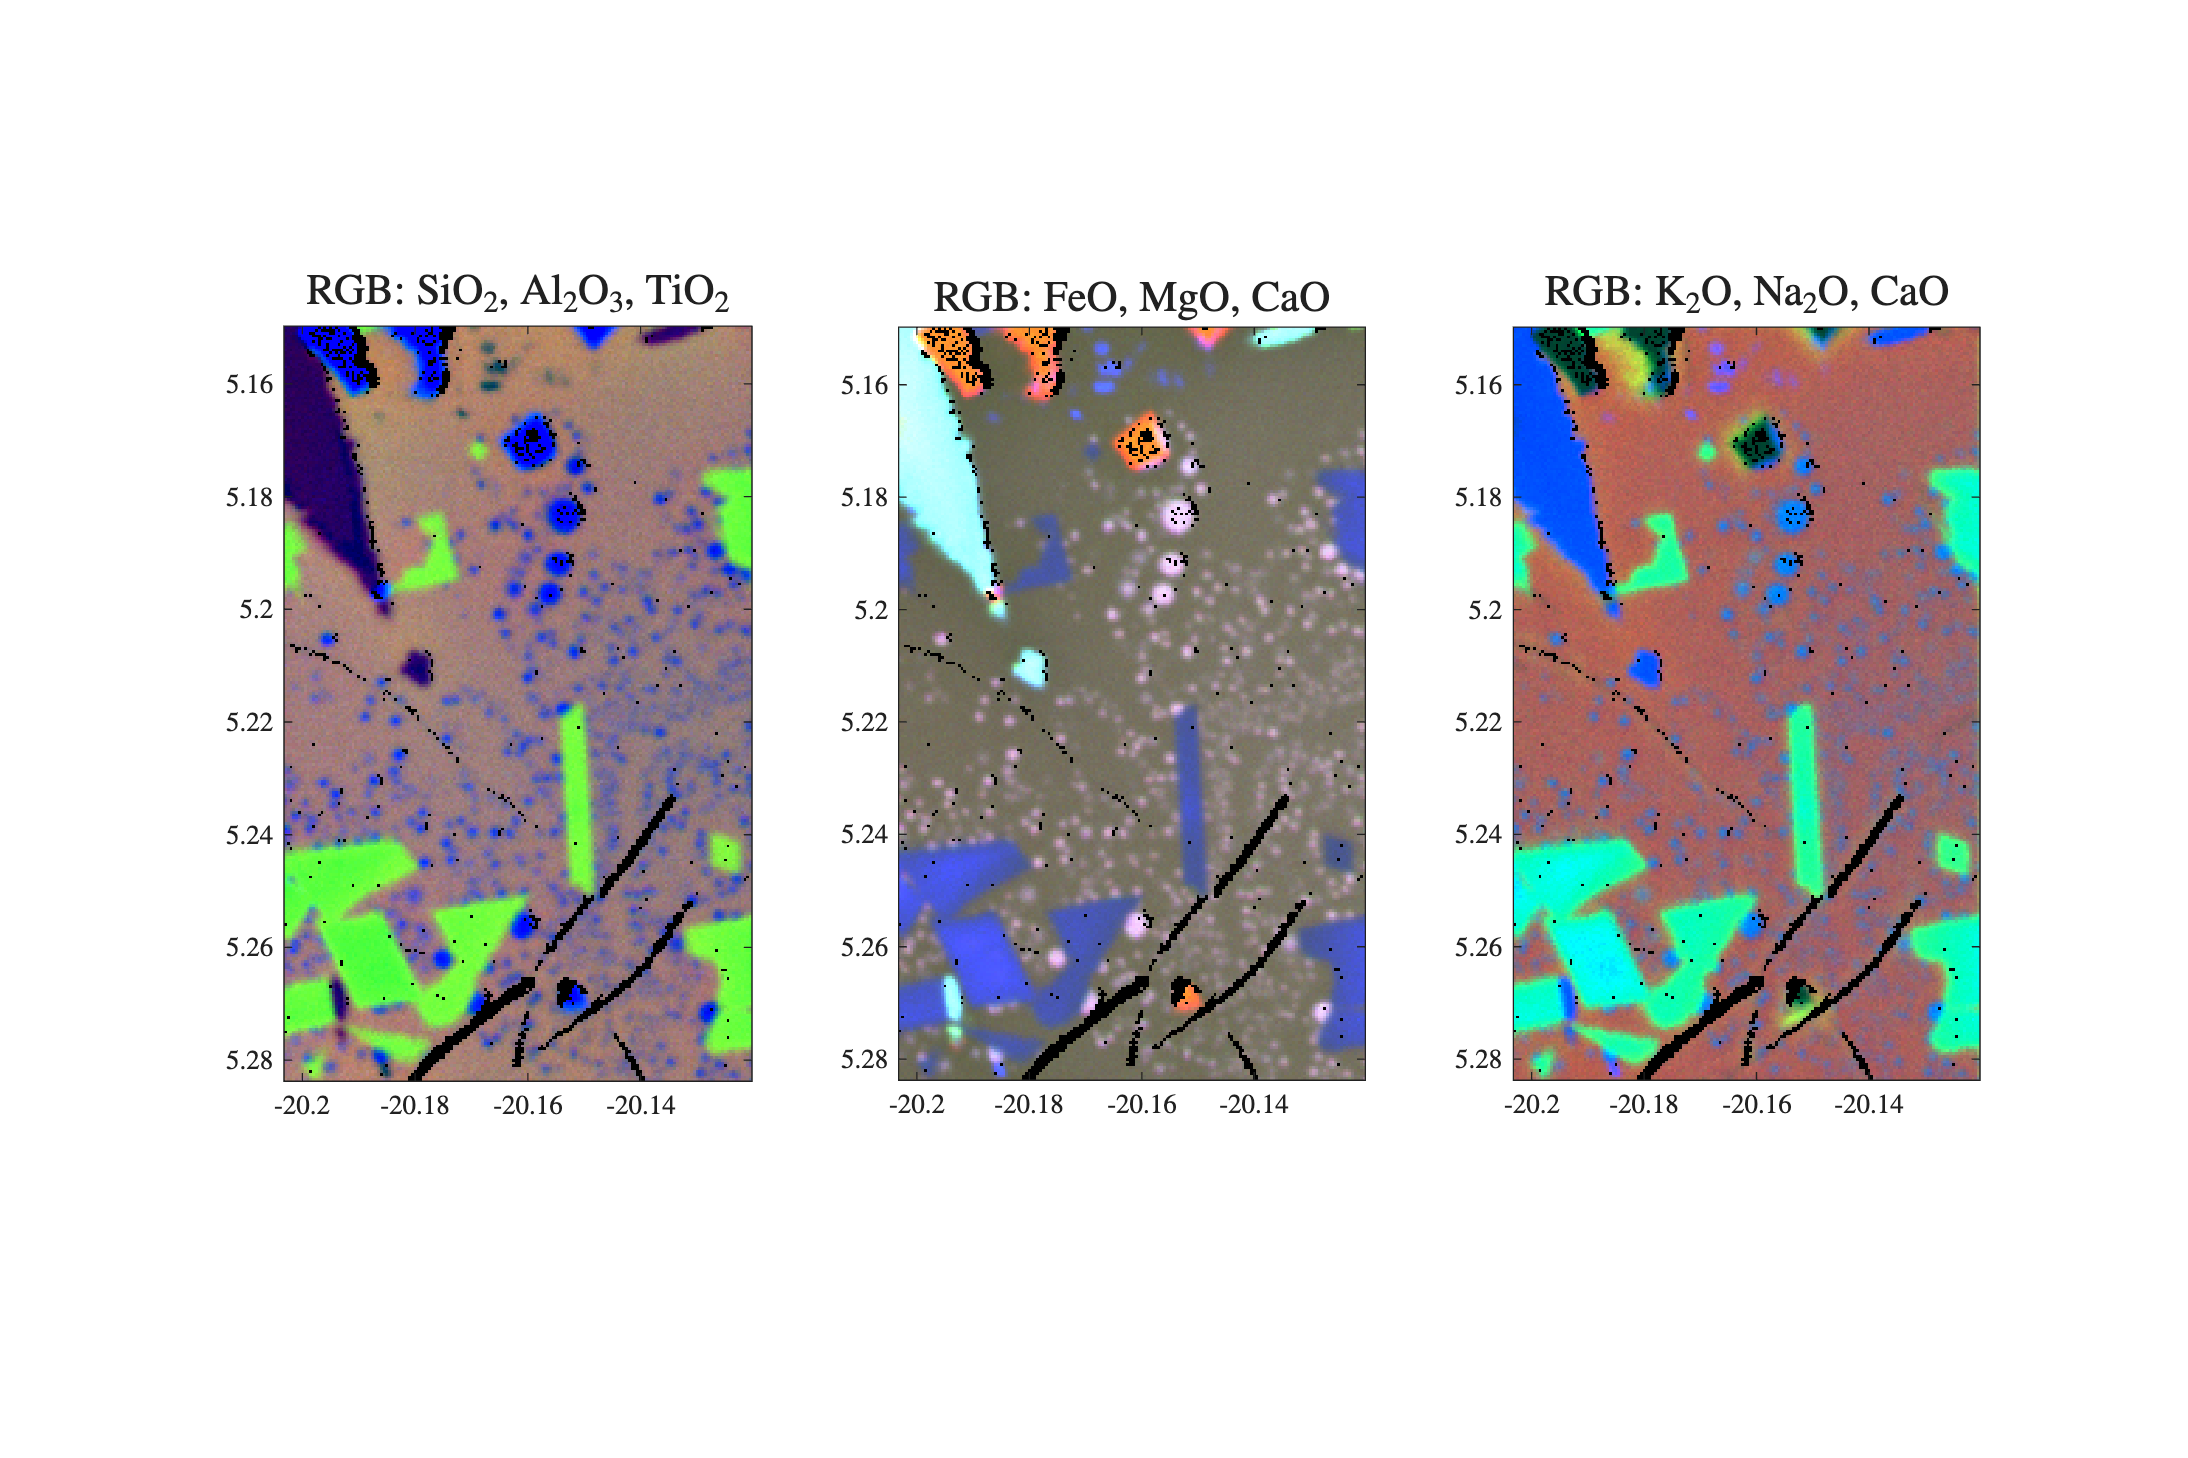

 

sat = 2;

fh4 = figure(4); clf;
set(fh4,UN{:},'Position',[1 1 12 8]);

subplot(1,3,1)
RGB = OxdVec(:,[Si,Al,Ti]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: SiO$_2$, Al$_2$O$_3$, TiO$_2$',TX{:},FL{:})

subplot(1,3,2)
RGB = OxdVec(:,[Fe,Mg,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: FeO, MgO, CaO',TX{:},FL{:})

subplot(1,3,3)
RGB = OxdVec(:,[K,Na,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: K$_2$O, Na$_2$O, CaO',TX{:},FL{:})

**Fig. 4:** False-colour images of raw oxide data showing images of (left to right) RGB = [TiO2, SiO2, Al2O3]; [FeO, MgO, CaO]; [K2O, Na2O, CaO].

## Filter and Scale Data

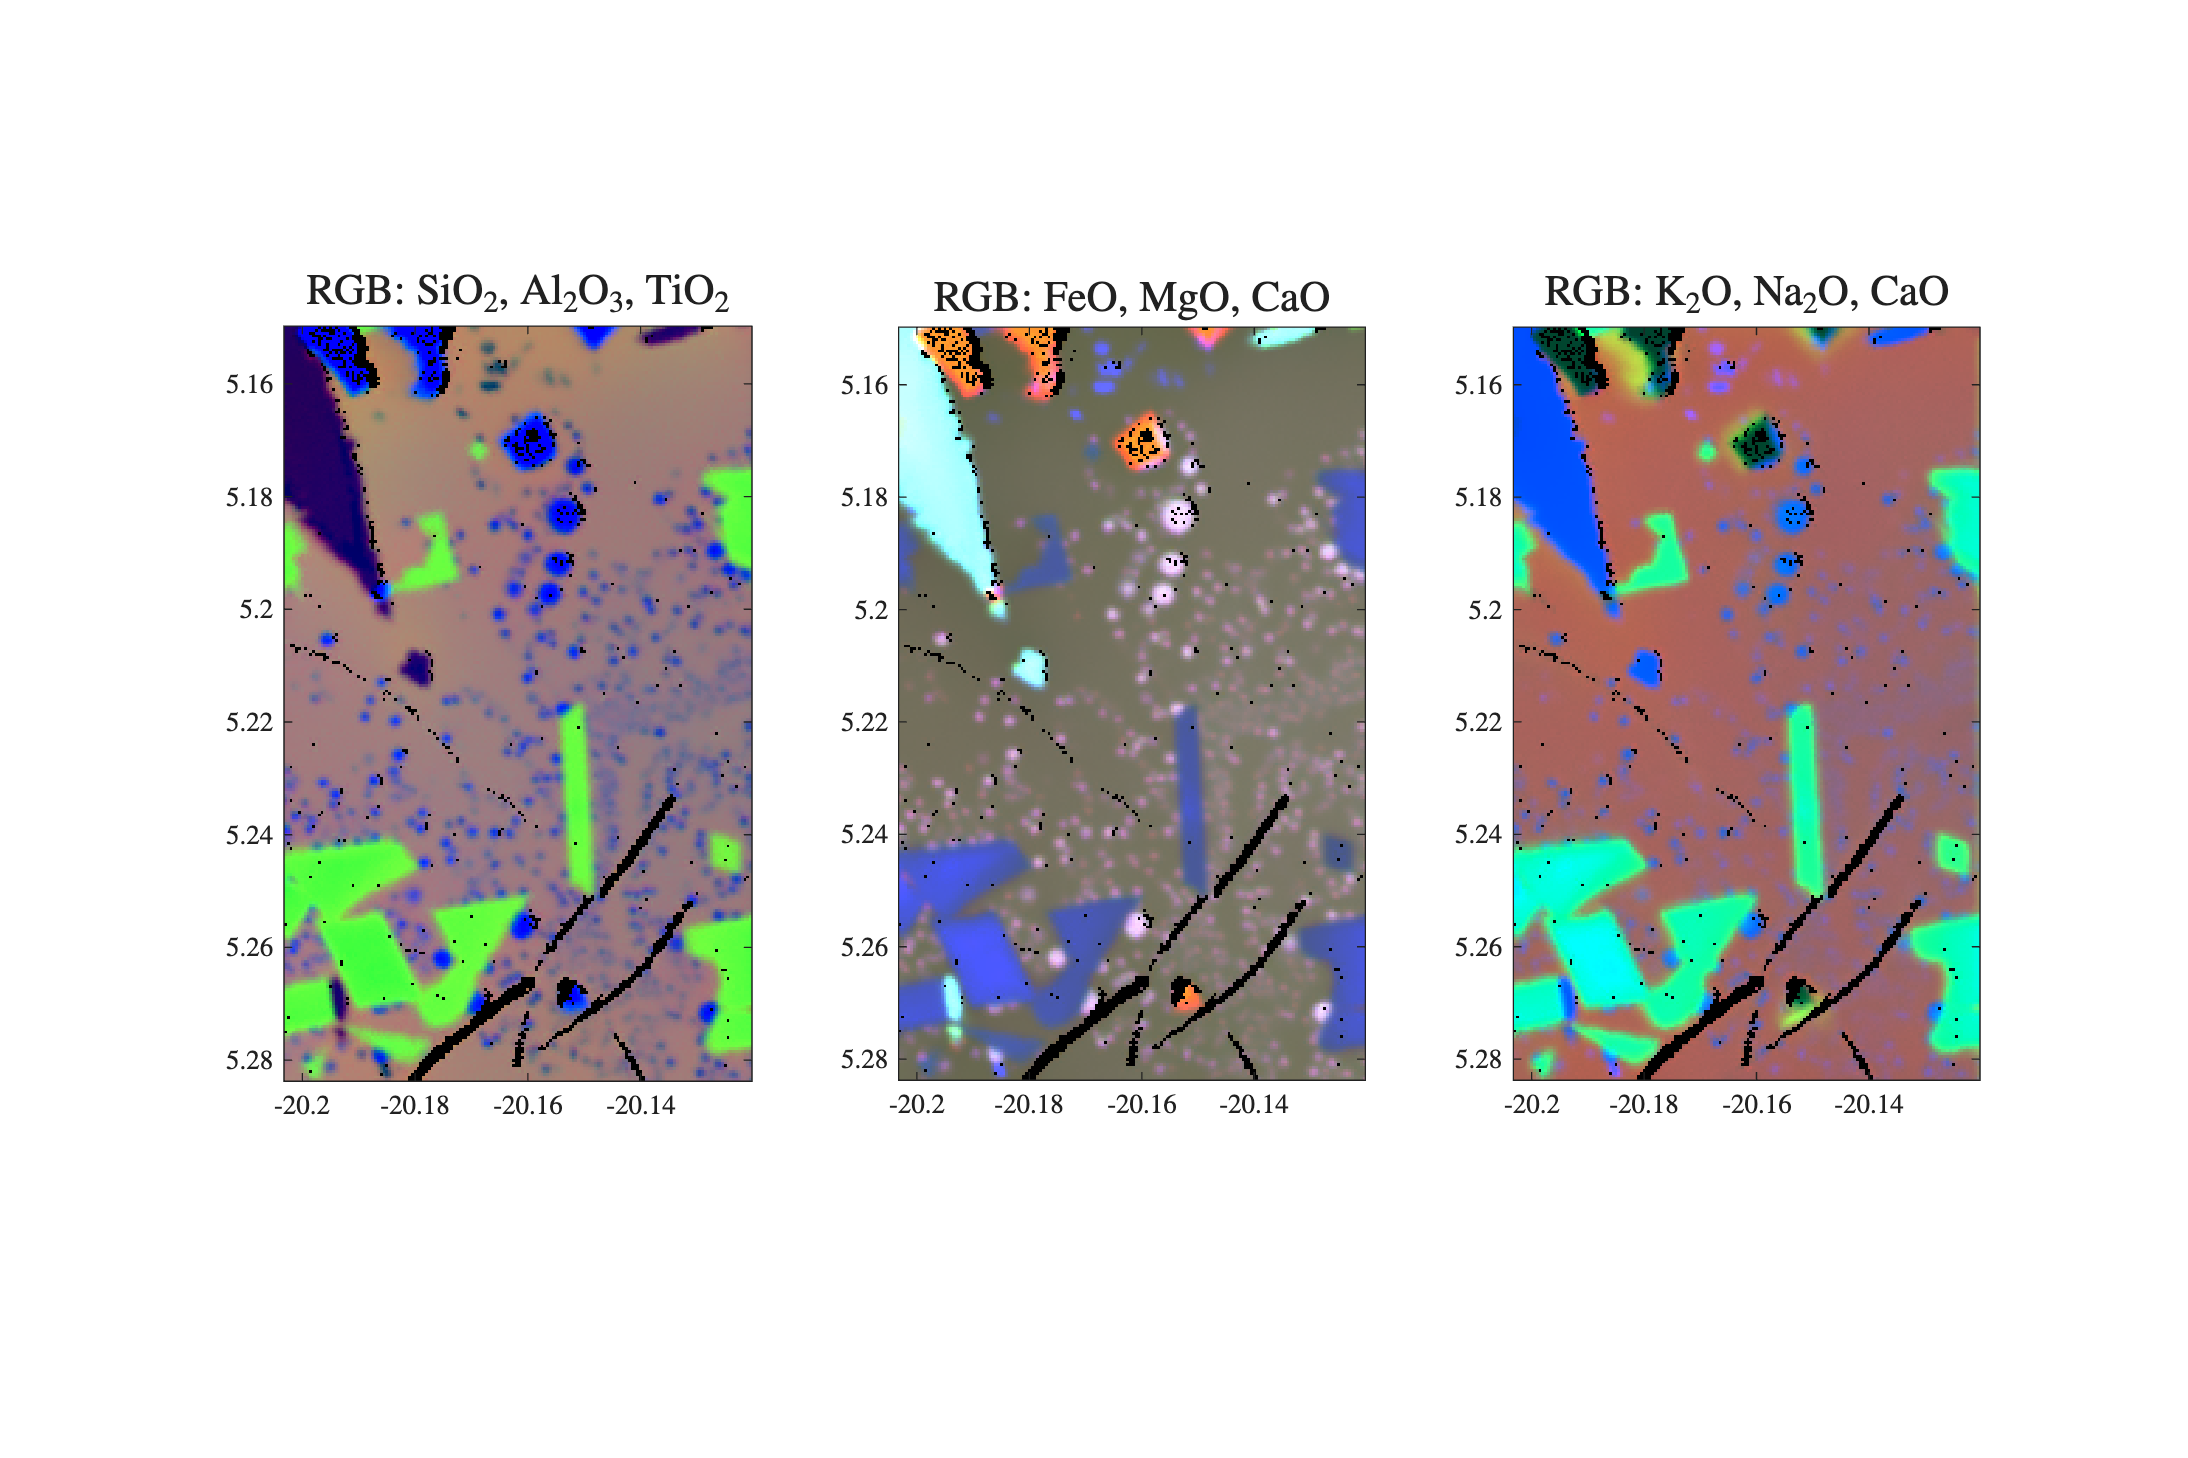

 

smth = 0.4;

for i = 1:k
    MAP = reshape(OxdVec0(:,i).*valvec,nx,nz);
    MAP = imnlmfilt(MAP,'DegreeOfSmoothing',smth);
    OxdVec(:,i) = MAP(:);
end

% normalise data to unit sum for relative intensities
OxdVec(:,1:k)  =  OxdVec(:,1:k)./(sum(OxdVec(:,1:k),2)+1e-32);

% plot filtered and rescaled results
fh5 = figure(5); clf;
set(fh5,UN{:},'Position',[1 1 12 8]);

subplot(1,3,1)
RGB = OxdVec(:,[Si,Al,Ti]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: SiO$_2$, Al$_2$O$_3$, TiO$_2$',TX{:},FL{:})

subplot(1,3,2)
RGB = OxdVec(:,[Fe,Mg,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: FeO, MgO, CaO',TX{:},FL{:})

subplot(1,3,3)
RGB = OxdVec(:,[K,Na,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: K$_2$O, Na$_2$O, CaO',TX{:},FL{:})

**Fig. 5:** False-colour images of filtered and rescaled oxide data showing images of (left to right) RGB = [TiO2, SiO2, Al2O3]; [FeO, MgO, CaO]; [K2O, Na2O, CaO].

## Perform Principal Component Analysis

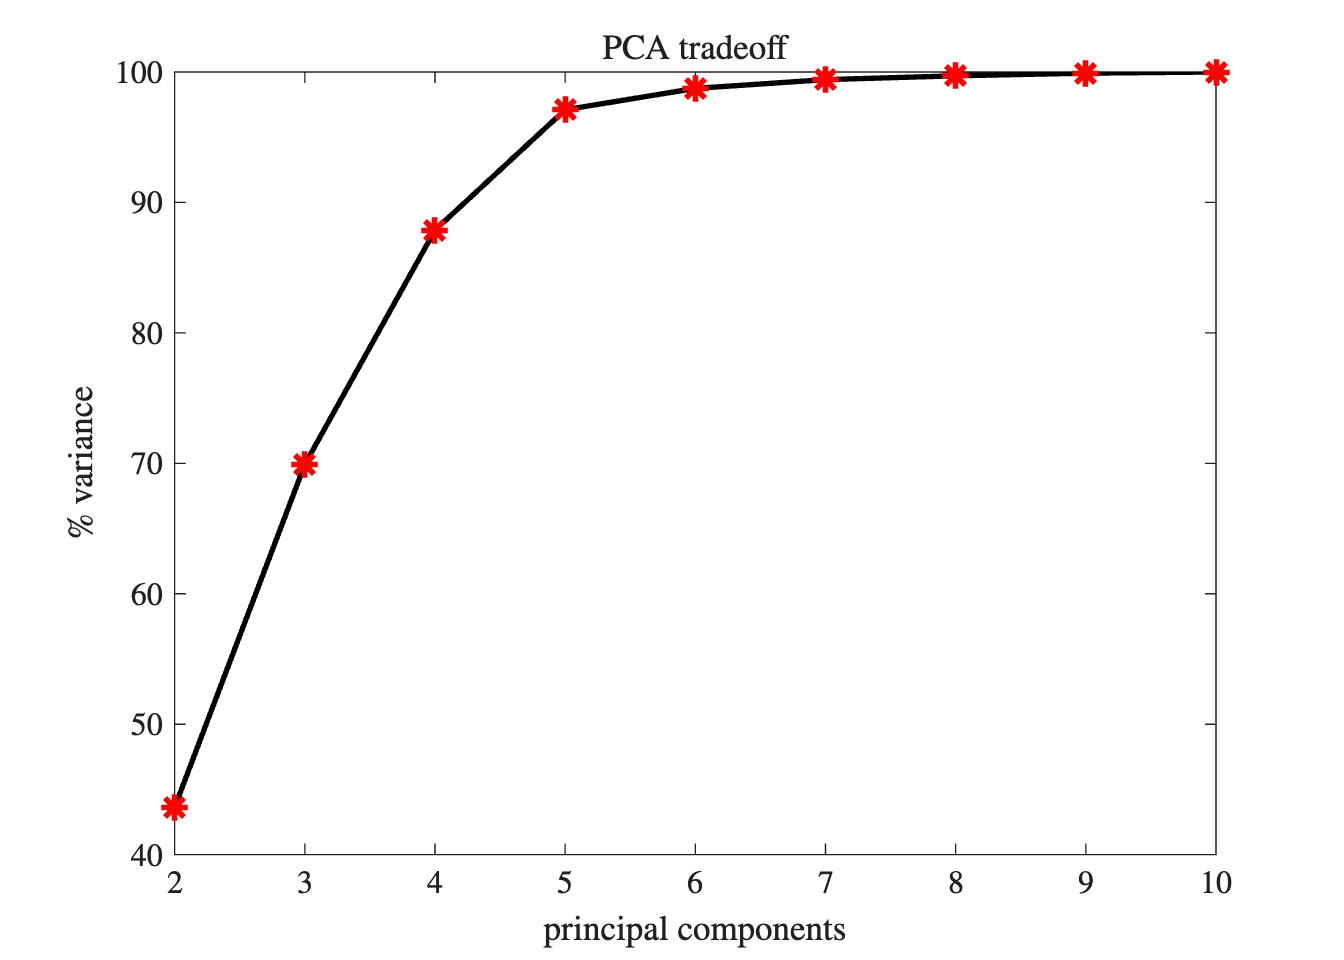

 

% perform principal component analysis
[PC, PA, PV] = pca(OxdVec(valvec,1:k),'Algorithm','svd','Centered','on','VariableWeights','variance');
PC = PC.';
CV = cumsum(PV(1:end-1)./sum(PV(1:end-1)));

% plot tradeoff curve
fh6 = figure(6); clf;
set(fh6,UN{:},'Position',[1 1 7 5]);

plot(2:k,CV*100,'k-',2:k,CV*100,'r*',LW{:},MS{:})
title('PCA tradeoff',TX{:},FL{:})
xlabel('principal components',TX{:},FL{:})
ylabel('\% variance',TX{:},FL{:})
set(gca,TL{:},FS{:},'Xtick',2:k)

**Fig. 6:** Principal component tradeoff curve showing cumulative percentage of variance versus number of principal components retained.

## Reduce Data Dimensions

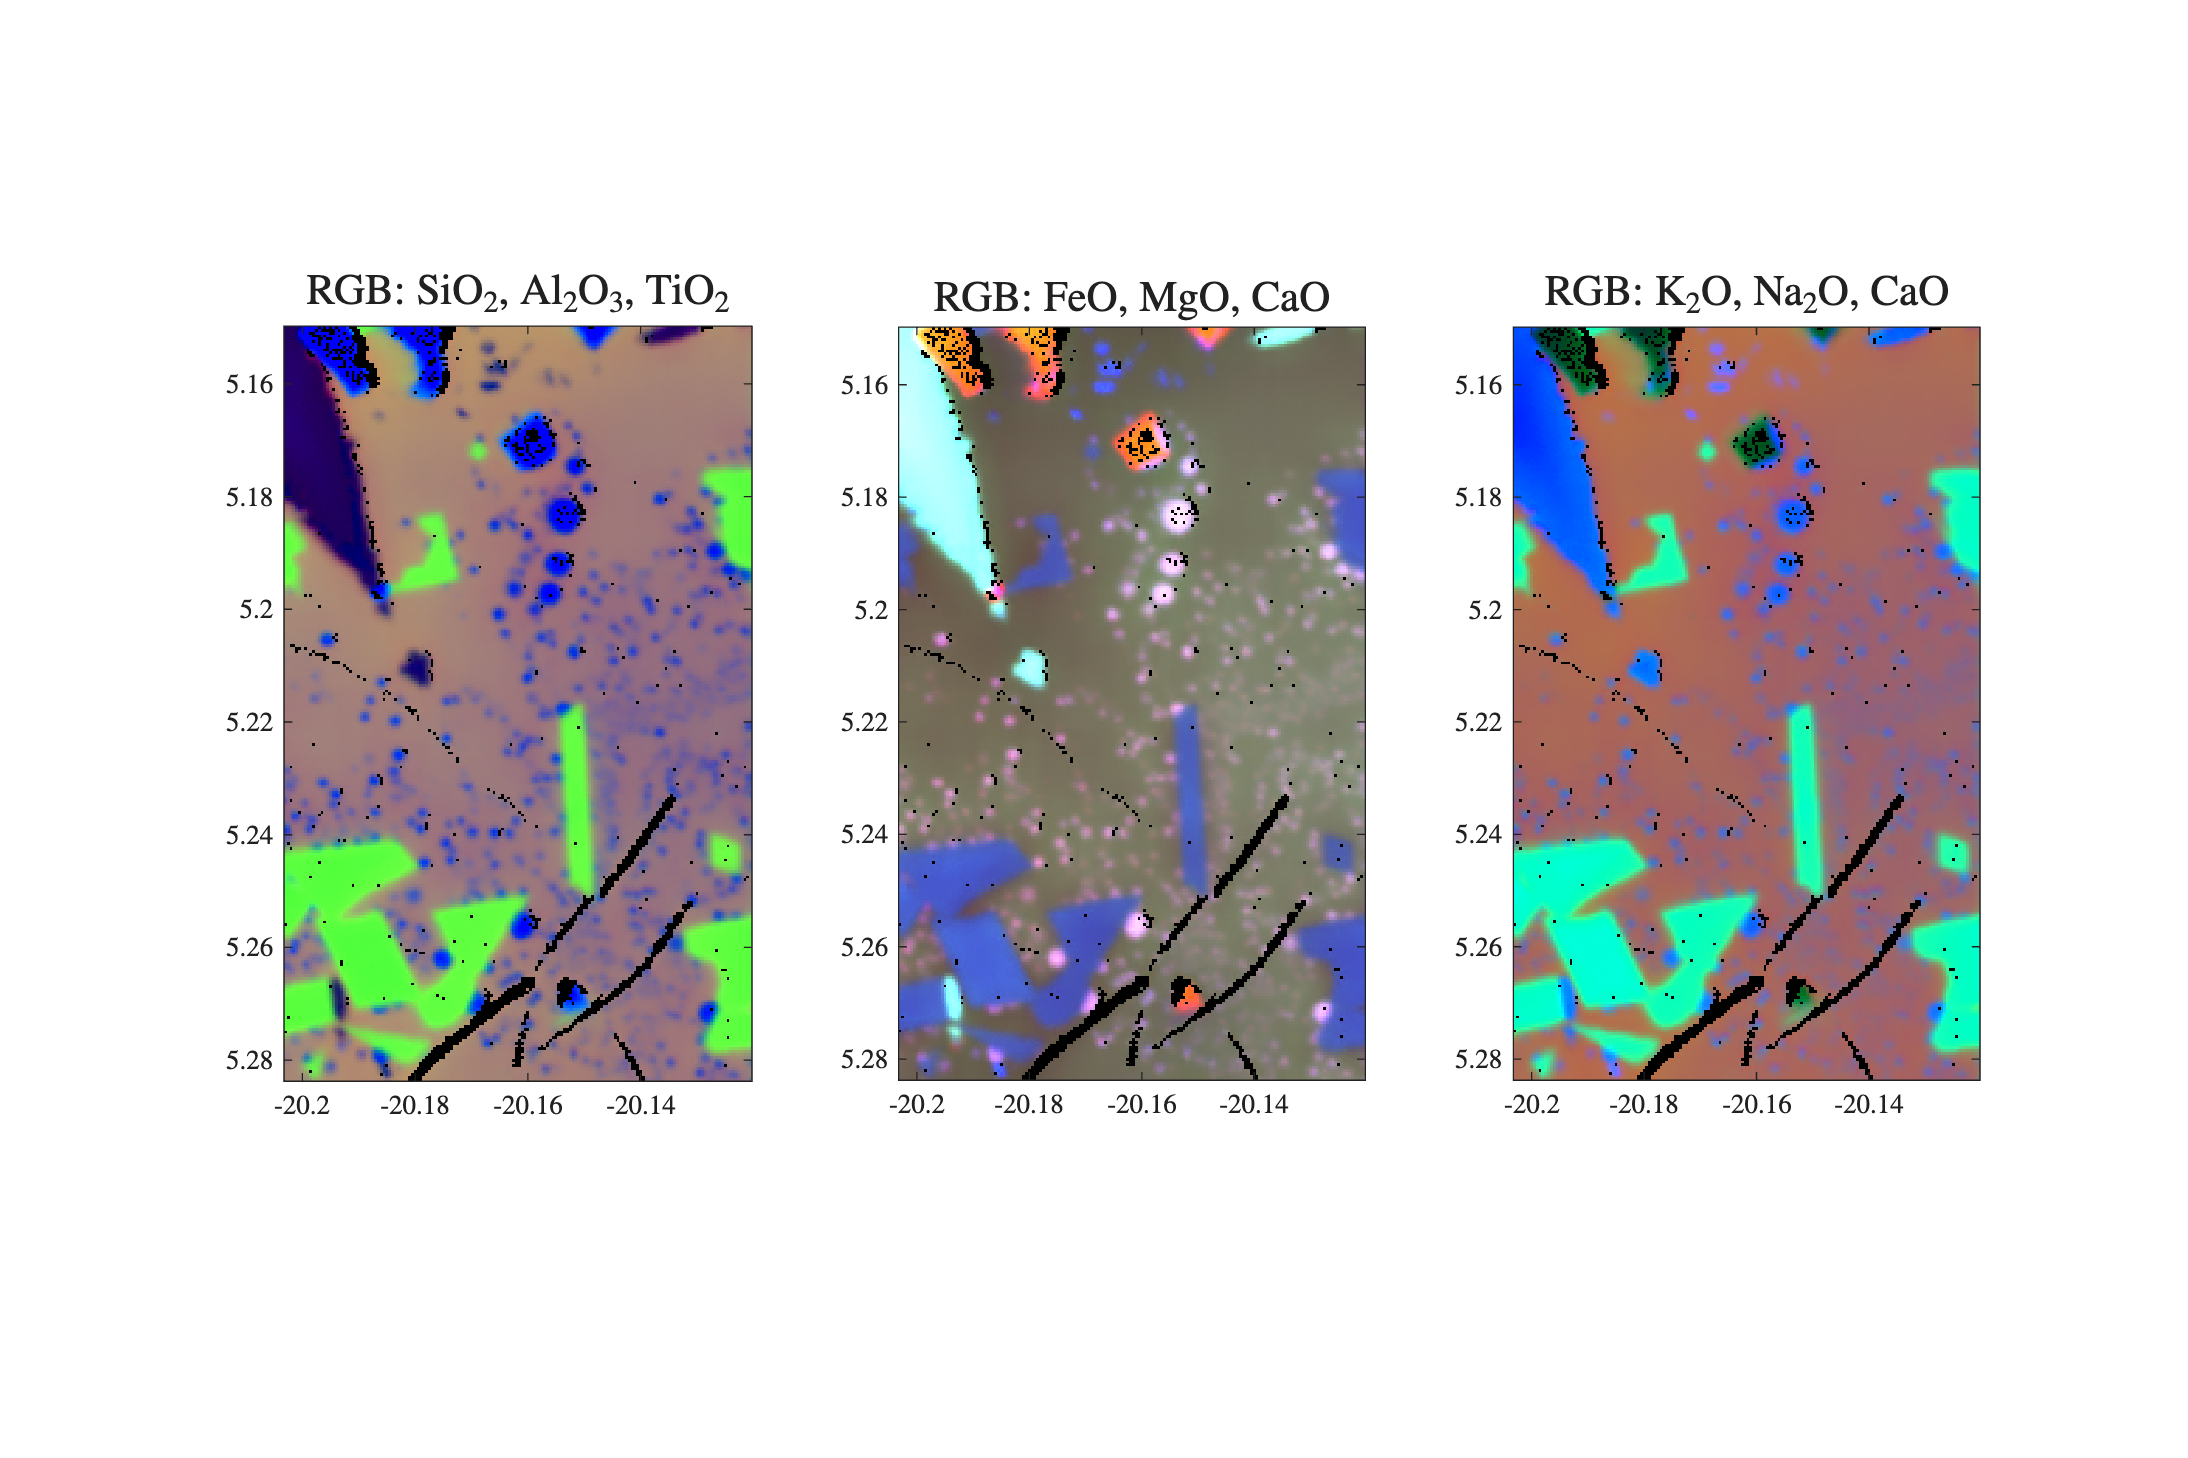

 

p =4;

% reduce data to p principal components
Fp = PC(1:p,:);
Ap = zeros(size(OxdVec,1),p);
Ap(valvec,:) = PA(:,1:p);
OxdPC = Ap*Fp + mean(OxdVec(:,1:k).*valvec);
Rp = sum((OxdPC-OxdVec(:,1:k).*valvec).^2,2)./sum((OxdVec(:,1:k).*valvec).^2,2);

fh7 = figure(7); clf;
set(fh7,UN{:},'Position',[1 1 12 8]);

subplot(1,3,1)
RGB = OxdPC(:,[Si,Al,Ti]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: SiO$_2$, Al$_2$O$_3$, TiO$_2$',TX{:},FL{:})

subplot(1,3,2)
RGB = OxdPC(:,[Fe,Mg,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: FeO, MgO, CaO',TX{:},FL{:})

subplot(1,3,3)
RGB = OxdPC(:,[K,Na,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: K$_2$O, Na$_2$O, CaO',TX{:},FL{:})

**Fig. 7:** False-colour images of reduced data showing images of (left to right) RGB = [TiO2, SiO2, Al2O3]; [FeO, MgO, CaO]; [K2O, Na2O, CaO].

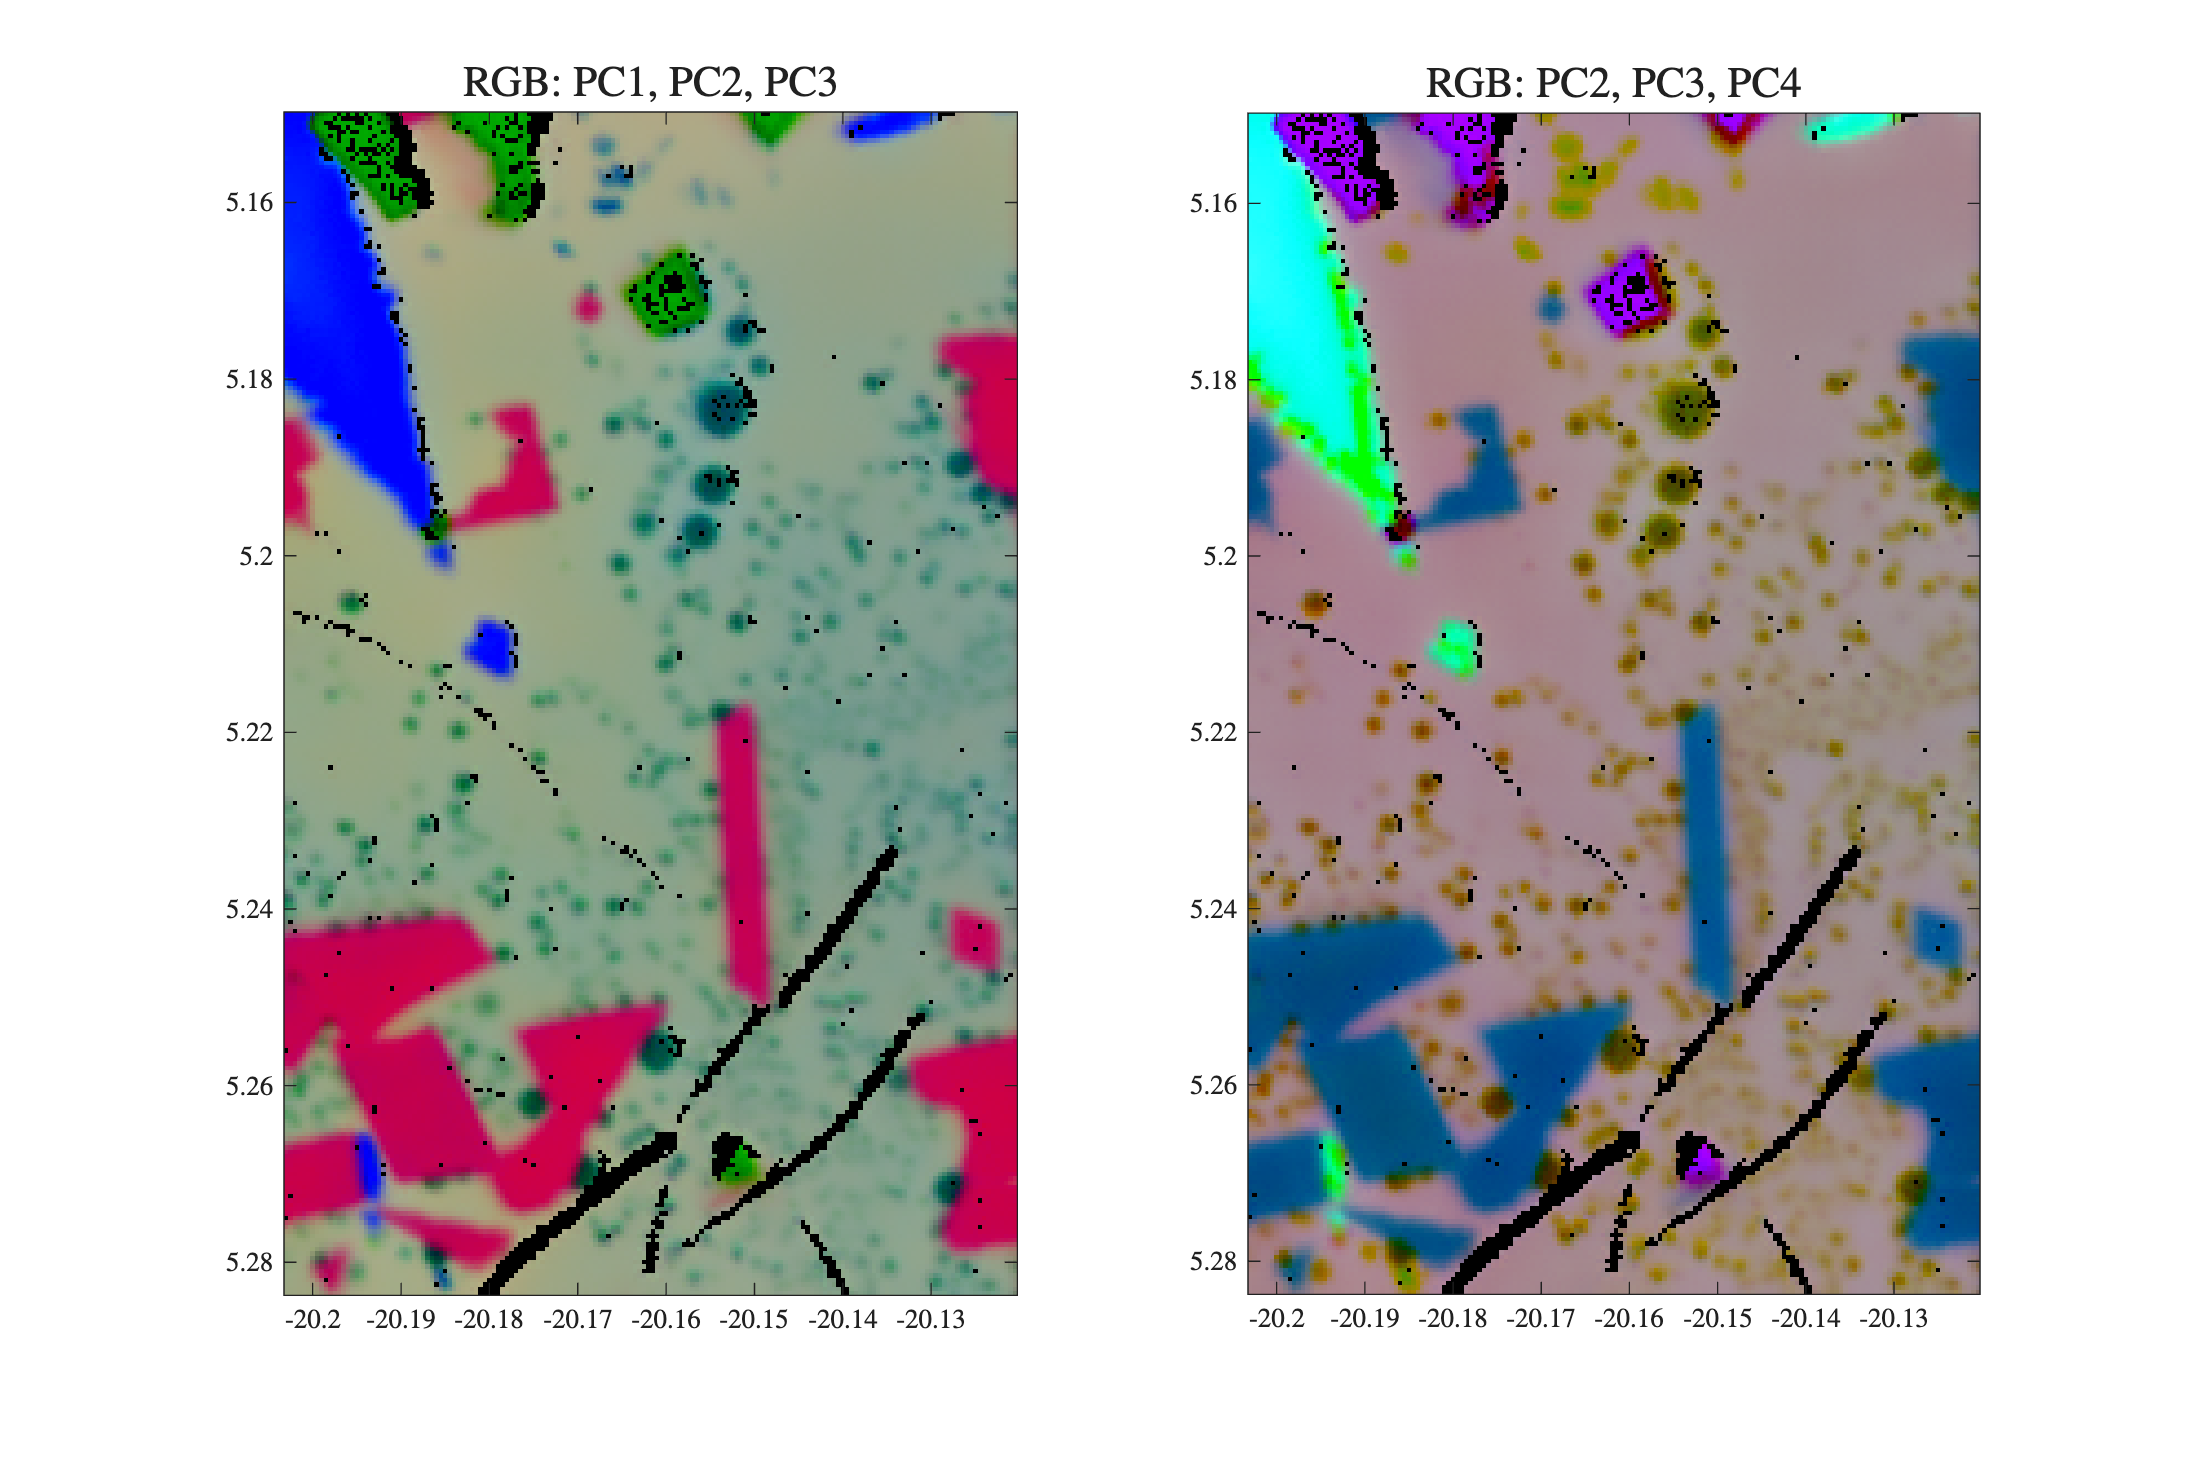

maxV = 1.787e+04


minV = 8.847e+04


minV/maxV = 4.95


min(AExt) = -0.04373, min(FExt) = -0.03004


fh8 = figure(8); clf;
set(fh8,UN{:},'Position',[1 1 12 8]);

subplot(1,2,1)
ic = [1,2,min(3,p)];
RGB = Ap(:,ic);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title(['RGB: PC',int2str(ic(1)),', PC',int2str(ic(2)),', PC',int2str(ic(3))],TX{:},FL{:})

subplot(1,2,2)
ic = [max(1,p-2),max(2,p-1),max(2,p)];
RGB = Ap(:,ic);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title(['RGB: PC',int2str(ic(1)),', PC',int2str(ic(2)),', PC',int2str(ic(3))],TX{:},FL{:})

## Perform Clustering Analysis

 

c =6;

% perform k-means clustering analysis
opts = statset('Display','final');
rng(15);
[Ic,Fc] = kmeans(Ap(valvec,:),c,'MaxIter',1e3,'Replicates',10,'Options',opts);

Replicate 1, 18 iterations, total sum of distances = 48609.4.
Replicate 2, 34 iterations, total sum of distances = 48609.4.
Replicate 3, 35 iterations, total sum of distances = 48609.4.
Replicate 4, 41 iterations, total sum of distances = 48609.4.
Replicate 5, 40 iterations, total sum of distances = 48609.4.
Replicate 6, 32 iterations, total sum of distances = 48609.3.
Replicate 7, 36 iterations, total sum of distances = 58125.6.
Replicate 8, 13 iterations, total sum of distances = 58121.9.
Replicate 9, 25 iterations, total sum of distances = 48609.4.
Replicate 10, 40 iterations, total sum of distances = 48609.4.
Best total sum of distances = 48609.3


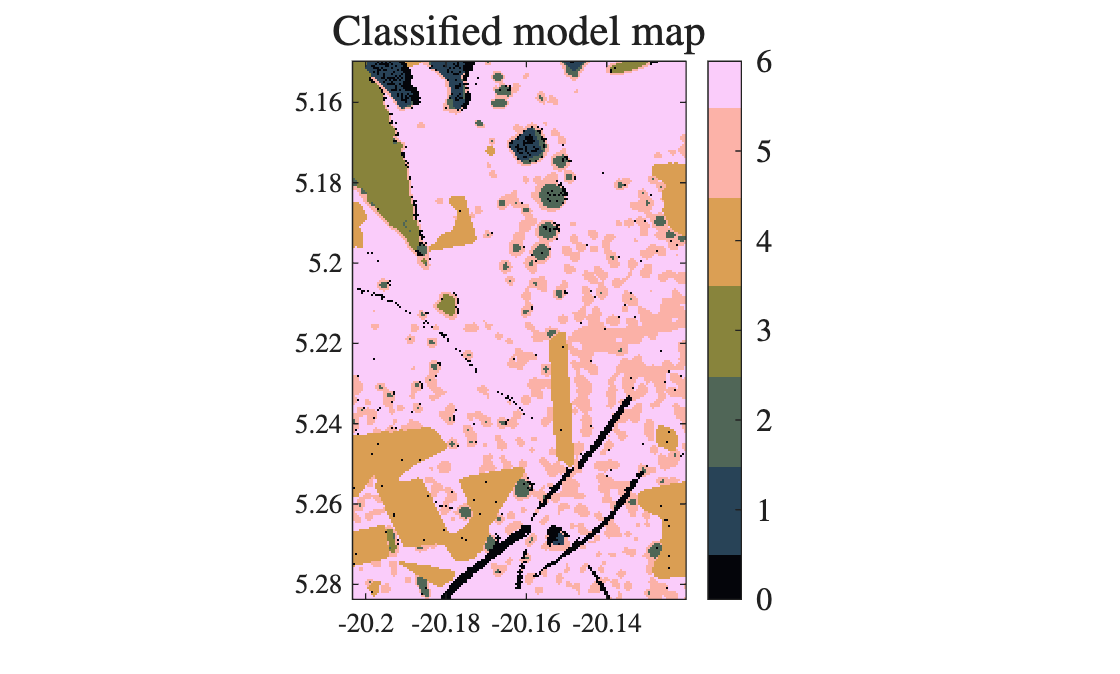

Icfull = zeros(size(valvec));
Icfull(valvec,1) = Ic;

% get cluster compositions in oxides
ClstOxdMean = zeros(c,k);
ClstOxdStd  = zeros(c,k);
for ic = 1:c
    ClstOxdMean(ic,:) = mean(OxdVec(Icfull==ic,1:k));
    ClstOxdStd(ic,:)  =  std(OxdVec(Icfull==ic,1:k));
end

% sort clusters for ascending SiO2 content
[~,isort]   = sort(ClstOxdMean(:,1),'ascend');
ClstOxdMean = ClstOxdMean(isort,:);
ClstOxdStd  = ClstOxdStd (isort,:);
Icfull_sort = zeros(size(valvec));
for ic = 1:c
    Icfull_sort(Icfull==isort(ic)) = ic;
end
Icfull = Icfull_sort;

%% plot trained model map
ColorClass = batlowK(max(1,min(256,1+round((1:256)/(256/c))*round(256/c))),:);

fh9 = figure(9); clf;
set(fh9,'Units','inches','Position',[1 1 10 8]);

imagesc(X,Z,fliplr(reshape(Icfull,nx,nz).')); colormap(ColorClass); colorbar(TL{:},FS{:}); axis equal tight;
title('Classified model map',FL{:},TX{:})
set(gca,TL{:})

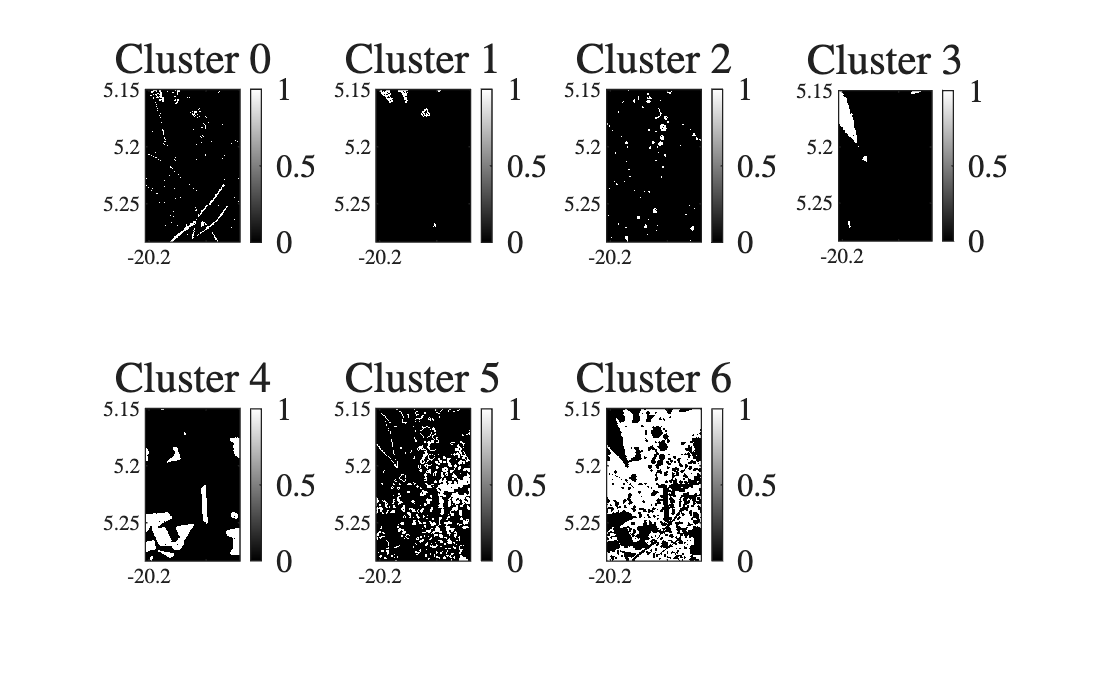


% plot clusters separately
fh10 = figure(10); clf;
set(fh10,'Units','inches','Position',[1 1 16 12]);

Nrow = floor(sqrt(c+1));
Ncol = ceil((c+1)/Nrow);

for nplt=1:c+1
    subplot(Nrow,Ncol,nplt)
    imagesc(X,Z,fliplr(reshape(Icfull==(nplt-1),nx,nz).')); colormap(gray); colorbar(TL{:},FS{:}); axis equal tight;
    set(gca,TL{:})
    title(['Cluster ',int2str(nplt-1)],FL{:},TX{:})
end

Cluster compositions mean (wt% SiO$_2$, TiO$_2$, Al$_2$O$_3$, FeO, MgO, CaO, Na$_2$O, K$_2$O)

disp(ClstOxdMean*100)

    7.9756   15.1035    3.6194   67.4869    2.5559    1.1282    0.4738    0.3871    0.9415    0.3280
   46.5828    4.6667    8.4674   17.4752    3.4175    8.9450    1.4173    2.1045    6.6852    0.2384
   51.1665    1.1995    2.6399   13.9350   13.5331   15.4948    0.4229    0.2781    0.8871    0.4430
   60.0522    0.3882   23.3367    1.7171    0.2681    6.7128    5.9240    1.2949    0.2250    0.0810
   61.7086    2.5118   12.2857   10.1317    1.7831    4.4112    1.1250    3.7736    2.0578    0.2115
   67.8439    1.8059   13.8618    6.3415    1.1119    2.5829    1.0489    4.3810    0.8465    0.1755



Cluster compositions standard deviation (wt% SiO$_2$, TiO$_2$, Al$_2$O$_3$, FeO, MgO, CaO, Na$_2$O, K$_2$O)

disp(ClstOxdStd*100)

    9.1237    2.7733    2.0790   10.3242    0.8724    1.5132    0.6568    0.4838    1.4635    0.0922
    7.8410    2.1130    2.2531    7.7680    1.7382    2.6619    0.8511    0.9829    2.4516    0.0797
    2.6821    0.4046    1.3392    2.5526    2.2773    2.7279    0.2026    0.4986    1.4677    0.0877
    2.4798    0.3709    2.5439    1.1564    0.3200    1.6752    0.7938    0.6429    0.3458    0.0386
    3.6636    0.7480    1.1343    3.2260    0.8676    1.2811    0.5658    0.4829    0.8272    0.0397
    1.5246    0.2646    0.7518    1.0560    0.2858    0.5139    0.4987    0.2939    0.2796    0.0388



 

p_em = p + 1;

mX = mean(OxdVec(valvec,1:k), 1);

% use cell to save cluster result
FInt_c  = cell(c,1);  FIntp_c = cell(c,1);  AInt_c = cell(c,1);  maxV_c = nan(c,1);
FExt_c  = cell(c,1);  FExtp_c = cell(c,1);  AExt_c = cell(c,1);  minV_c = nan(c,1);

for ic = 1:c
    idx = (Ic == ic);               % cluster ic 在 valvec 子集内的样本
    Ap_c = Ap(idx,:);               % n_c × p

    n_c = size(Ap_c,1);

    % Check sample size: must be >= number of end-members
    if n_c < p_em
        fprintf('Cluster %d skipped: n=%d < p_em=%d\n', ic, n_c, p_em);
        continue
    end

    % create cluster DGN
    DGNc = struct();
    DGNc.p     = p_em;              % 
    DGNc.Ii    = (1:n_c).';         % For the current cluster subset Ap_c, the valid sample indices run from 1 to n_c.
    DGNc.meanX = mX;                % 用全体 PCA 子集均值（推荐）
    DGNc.PC    = PC;                % 用同一套 PCA 变换

    % internal
    [FInt, FIntp, AInt, DGNc] = maximise(Ap_c, DGNc);

    % external
    [FExt, FExtp, AExt, DGNc] = minimise(Ap_c, FInt, DGNc);

    % save result
    FInt_c{ic}  = FInt;   FIntp_c{ic} = FIntp;  AInt_c{ic} = AInt;  maxV_c(ic) = DGNc.maxV;
    FExt_c{ic}  = FExt;   FExtp_c{ic} = FExtp;  AExt_c{ic} = AExt;  minV_c(ic) = DGNc.minV;

    fprintf('Cluster %d: n=%d, maxV=%.4g, minV=%.4g, ratio=%.4g\n', ...
        ic, n_c, maxV_c(ic), minV_c(ic), minV_c(ic)/maxV_c(ic));
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      21    9.367991e+00    2.906e-01    1.322e-01
    1      42    1.007658e+01    2.412e-01    9.454e-02    3.867e+00
    2      63    1.008783e+01    2.399e-01    9.408e-02    7.426e-02
    3      84    1.024593e+01    2.021e-01    8.787e-02    1.477e+00
    4     105    1.072367e+01    1.093e-01    6.796e-02    5.363e+00
    5     126    1.072834e+01    1.096e-01    6.786e-02    4.222e-02
    6     147    1.087483e+01    1.203e-01    6.622e-02    1.944e+00
    7     168    1.104000e+01    1.177e-01    6.289e-02    1.715e+00
    8     189    1.107517e+01    1.143e-01    6.144e-02    1.183e+00
    9     210    1.104568e+01    1.124e-01    6.226e-02    5.290e-01
   10     231    1.096879e+01    1.065e-01    6.363e-02    1.356e+00
   11     252    1.087342e+01    9.885e-02    6.498e-02    1.203e+00
   12     273    1.084247e+01    9.434e-02    6

Cluster 1: n=7895, maxV=1.171e+04, minV=7.527e+04, ratio=6.429


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      21    8.675231e+00    2.540e-01    1.185e-01
    1      42    9.517399e+00    2.046e-01    6.098e-02    4.094e+00
    2      63    9.538616e+00    2.020e-01    5.991e-02    1.084e-01
    3      84    9.848198e+00    1.585e-01    5.110e-02    3.252e+00
    4     105    9.988341e+00    1.543e-01    4.750e-02    1.179e+00
    5     126    1.017183e+01    1.478e-01    4.552e-02    1.551e+00
    6     147    1.021750e+01    1.425e-01    4.654e-02    4.821e-01
    7     168    1.040100e+01    1.237e-01    4.958e-02    1.786e+00
    8     189    1.038731e+01    1.273e-01    5.073e-02    9.767e-01
    9     210    1.048688e+01    1.154e-01    5.129e-02    1.915e+00
   10     231    1.059565e+01    9.348e-02    5.386e-02    2.460e+00
   11     252    1.059437e+01    9.247e-02    5.400e-02    6.145e-02
   12     273    1.057435e+01    7.833e-02    5